clc
clear
close all

# RVC Toolbox + Matlab native function

A robot can be defined by mean of a mathematical model described by omogeneous transformation matrices that are build following the so called Denavit-Hartenberg (DH) convention. 

Those matrices can be obtained in two different ways:

- Using the **native matlab function** *se(2)* (2D planar robot) or *se(3)* (3D robot).

- Using the **RVC Toolbox**: ETS2 or ETS3

## Direct Kinematics

#### Example 1) 2D ROBOT

Suppose we would like to model the robot in the following figure:

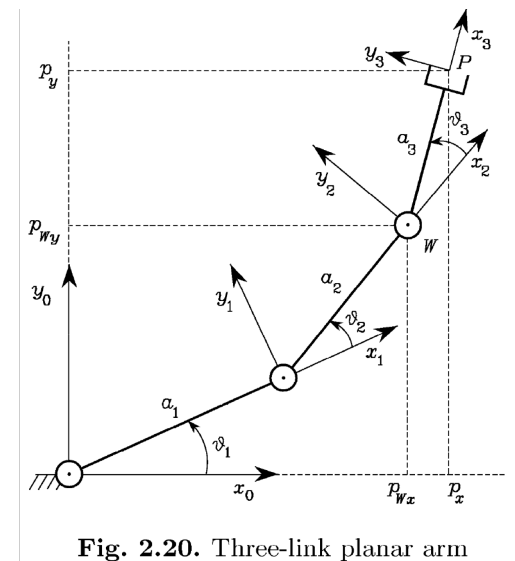

and obtain is direct kinematic that we know to be:

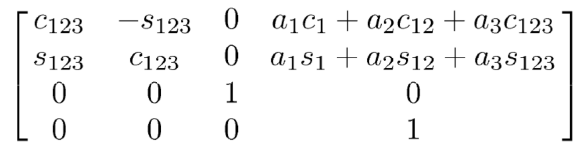

syms theta1 theta2 theta3 a1 a2 a3
cos123 = cos(theta1+theta2+theta3);
sin123 = sin(theta1+theta2+theta3);
T_reference = [cos123 -sin123 0 a1*cos(theta1)+a2*cos(theta1 + theta2)+a3*cos123;
               sin123 cos123 0 a1*sin(theta1)+a2*sin(theta1 + theta2)+a3*sin123;
               0 0 1 0;
               0 0 0 1]; 
T_reference = double(subs(T_reference,[theta1 theta2 theta3 a1 a2 a3],[deg2rad(20)*ones(1,3) ones(1,3)]));

#### Using RVC Toolbox

a1 = 1;
link1 = ETS2.Rz("q1")*ETS2.Tx(a1)

 
link1 = 
Rz(q1)Tx(1)


a2 = 1;
link2 = ETS2.Rz("q2")*ETS2.Tx(a2)

 
link2 = 
Rz(q2)Tx(1)


a3 = 1;
link3 = ETS2.Rz("q3")*ETS2.Tx(a3)

 
link3 = 
Rz(q3)Tx(1)


R = link1*link2*link3

 
R = 
Rz(q1)Tx(1)Rz(q2)Tx(1)Rz(q3)Tx(1)


Once we have modelled all the links/joints relation we can use the command *fkine([<angle in rad>])* on the object* R *to obtain the direct/forward kinematics of the joint

T = R.fkine(deg2rad(20*ones(3,1)))

T =     0.5000   -0.8660    2.2057
    0.8660    0.5000    1.8508
         0         0    1.0000


#### Using Matlab native functions

Equvalently we can use the matlab native function 

link1_ = se2(deg2rad(20),"theta")*se2(eye(2),[a1 0]);
link2_ = se2(deg2rad(20),"theta")*se2(eye(2),[a2 0]);
link3_ = se2(deg2rad(20),"theta")*se2(eye(2),[a3 0]);

T_ = link1_*link2_*link3_

T_ = se2
    0.5000   -0.8660    2.2057
    0.8660    0.5000    1.8508
         0         0    1.0000


Usign the command *printtform2d()* I can retrive the position and the angle of the end effector with respect the base reference system  

printtform2d(se2(T),unit="deg")

t = (2.21, 1.85), 60 deg


If I want a graphical representation of the 2D robots I can use the command *teach. *This command allow me to get the 2D position of the end-effector and the angle respect to the base reference system. With the slider in the figure I can modify the angle of the joints modifying also the configuration of the robot.   

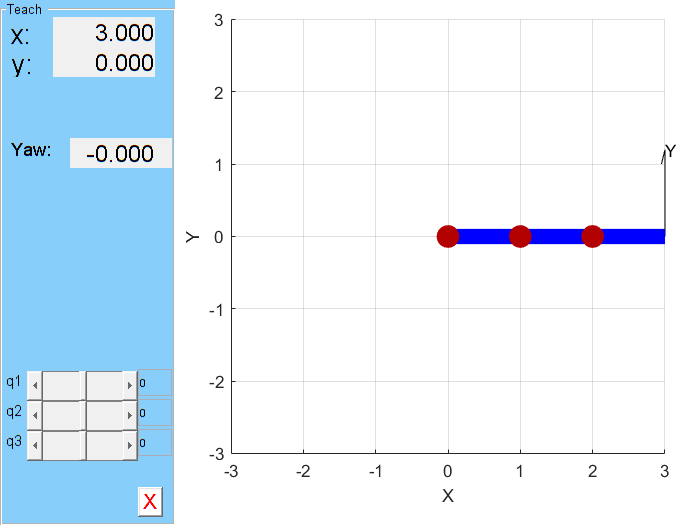

figure
R.teach

#### Example 2) 3D Robot

If I create a robot without following the DH convention te simulation will work properly anyway. For example:

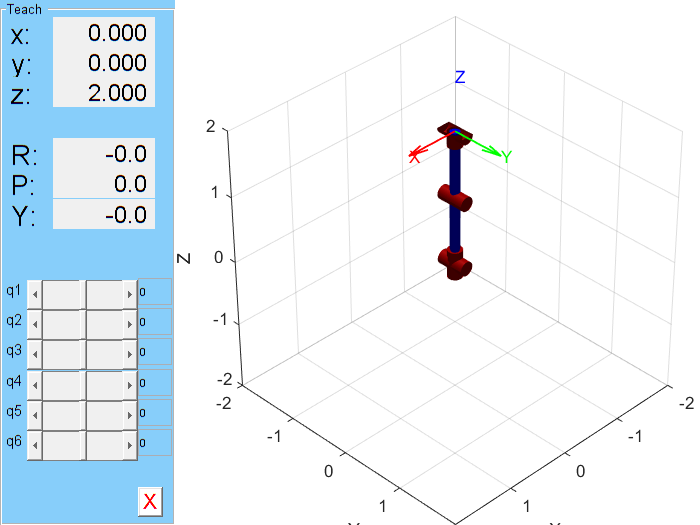

R = ETS3.Rz("q1")*ETS3.Ry("q2")*ETS3.Tz(a1)*ETS3.Ry("q3")*ETS3.Tz(a2)*ETS3.Rz("q4")*ETS3.Ry("q5")*ETS3.Rz("q6");
figure
R.teach

This description doesn't follow the DH convention because it uses Rotation and Translation only about the X and the Z axes. 

To explore the properties of the robot we can use:

R.njoints

ans = 6

R.structure

ans = 'RRRRRR'

R.fkine(zeros(1,6)); 

### Rigid Body Tree

Another way to modelling the robot is using the **Rigid Body Tree** from Matlab. This allow us to describe some properties that the robot links can have, such as mass,inertia and collision geometries.

a1 = 1; a2 = 2;
link1 = rigidBody("link1"); %We define the link
link1.Joint = rigidBodyJoint("joint1", "revolute"); % We associate a revolute joint to the link
link2 = rigidBody("link2");
link2.Joint = rigidBodyJoint("join2","revolute"); 

*link1* is the base link so we don't need to specify is position. In the case of *link2* instead we need to specify also the position respect to the base.

link2.Joint.setFixedTransform(se3([a1 0 0],"trvec"));
link3 = rigidBody("link3"); %end-effector
link3.Joint.setFixedTransform(se3([a2 0 0],"trvec"));


Most of the matlab function that work with the vector of generalized coordinates need a row format.

myRobot = rigidBodyTree("DataFormat","row"); 
myRobot.addBody(link1,myRobot.BaseName); %The second parameter is where the first parameter is attach
myRobot.addBody(link2,link1.Name); 
myRobot.addBody(link3,link2.Name); 

To compute the forward kinematic we need to use the functions *getTransform()*

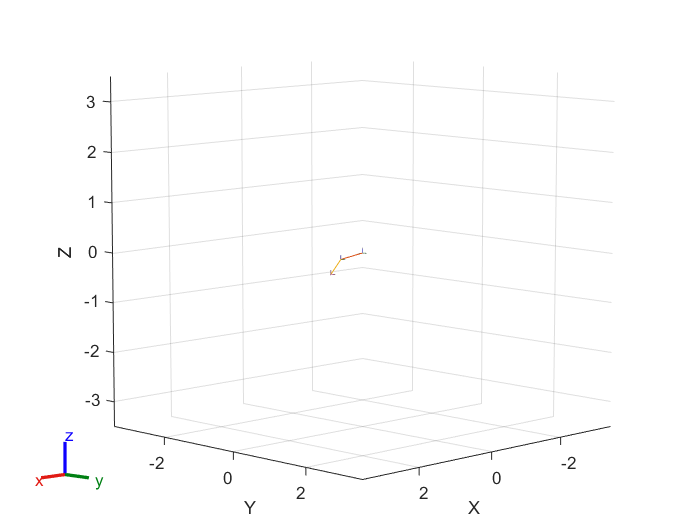

ans =   Axes (Primary) with properties:

             XLim: [-3.5000 3.5000]
             YLim: [-3.5000 3.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


T = myRobot.getTransform(deg2rad([20 20]),"link3");
figure
myRobot.show(deg2rad([20 20]))

 It is possible to transform the ETS representation into the Rigid Body Tree representation using the *ets2rbt() *method

myRobot6DOF = ets2rbt(R)

myRobot6DOF =   rigidBodyTree with properties:

     NumBodies: 8
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'link1'  'link2'  'link3'  'link4'  'link5'  'link6'  'link7'  'link8'}
      BaseName: 'base'
       Gravity: [0 0 0]
    DataFormat: 'row'


myRobot6DOF.showdetails

--------------------
Robot: (8 bodies)

 Idx    Body Name    Joint Name    Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------    ----------    ----------    ----------------   ----------------
   1        link1            q1      revolute             base(0)   link2(2)  
   2        link2            q2      revolute            link1(1)   link3(3)  
   3        link3        fixed1         fixed            link2(2)   link4(4)  
   4        link4            q3      revolute            link3(3)   link5(5)  
   5        link5        fixed2         fixed            link4(4)   link6(6)  
   6        link6            q4      revolute            link5(5)   link7(7)  
   7        link7            q5      revolute            link6(6)   link8(8)  
   8        link8            q6      revolute            link7(7)   
--------------------


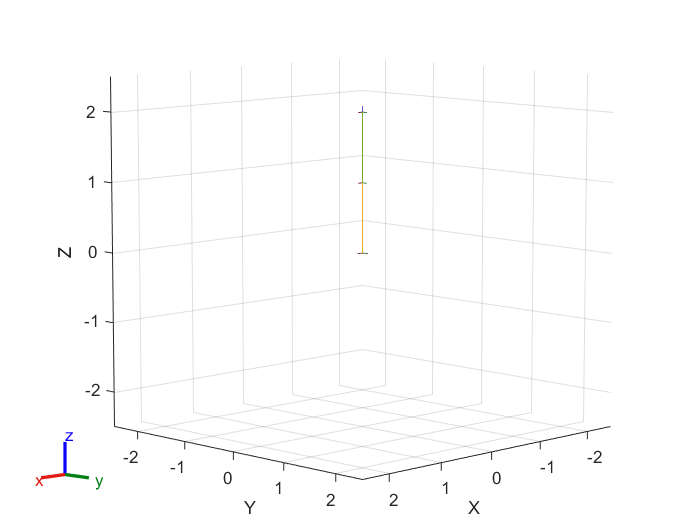

ans =   Axes (Primary) with properties:

             XLim: [-2.5000 2.5000]
             YLim: [-2.5000 2.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


figure
myRobot6DOF.show

We can also the *loadrobot * command to use some model of real commercial robots that have already been modeled.

panda = loadrobot("frankaEmikaPanda","DataFormat","row");
panda.showdetails

--------------------
Robot: (11 bodies)

 Idx                Body Name                 Joint Name                 Joint Type                Parent Name(Idx)   Children Name(s)
 ---                ---------                 ----------                 ----------                ----------------   ----------------
   1              panda_link1               panda_joint1                   revolute                  panda_link0(0)   panda_link2(2)  
   2              panda_link2               panda_joint2                   revolute                  panda_link1(1)   panda_link3(3)  
   3              panda_link3               panda_joint3                   revolute                  panda_link2(2)   panda_link4(4)  
   4              panda_link4               panda_joint4                   revolute                  panda_link3(3)   panda_link5(5)  
   5              panda_link5               panda_joint5                   revolute                  panda_link4(4)   panda_link6(6)  
   6          

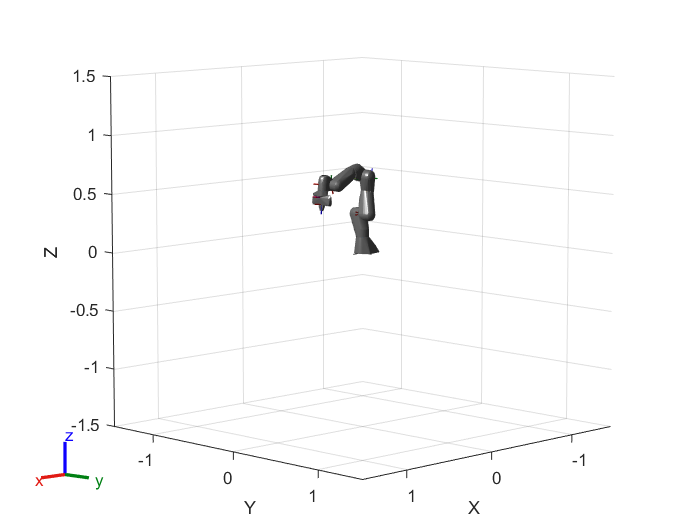

figure
conf = [0 -0.3 0 -2.2 0 2 0.7854 0 0];
panda.show(conf);

The *interactiveRigidBodyTree * allow us to play with the robot but it doesn't give us the real-time values of the joint variables as in the previous case. 

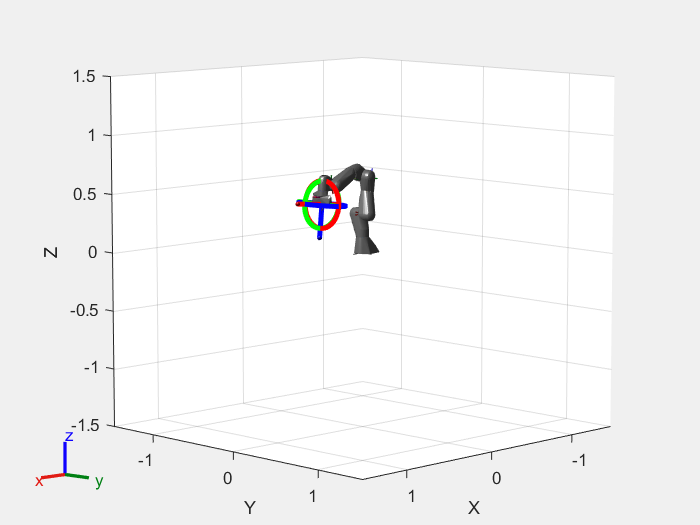

intPanda =   interactiveRigidBodyTree with properties:

           RigidBodyTree: [1×1 rigidBodyTree]
                IKSolver: [1×1 generalizedInverseKinematics]
       SolverPoseWeights: [1 1]
             Constraints: {}
          MarkerBodyName: 'panda_rightfinger'
     MarkerControlMethod: 'InverseKinematics'
       MarkerScaleFactor: 1
              ShowMarker: 1
           Configuration: [9×1 double]
    StoredConfigurations: []
              MarkerPose: [4×4 double]
          MarkerBodyPose: [4×4 double]


intPanda = interactiveRigidBodyTree(panda, Configuration=conf) 

If we want to retrive the angle needed to position the end-effector in a certain point in the space we can manually position the robot in the desidred configuration and than using the property *Configuration *of the* object *created for the interaction we can retrive the needed values of the joint variable 

a = intPanda.Configuration'

a =          0   -0.3000         0   -2.2000         0    2.0000    0.7854         0         0


### Build the rbt following the DH convention 

Using the DH convention we can define the model of the robot as well.

dhparams = [0 pi/2 0 0; 0.4318 0 0 0; 0.0203 -pi/2 0.15005 0; 0 pi/2 0.4318 0; 0 -pi/2 0 0; 0 0 0 0];
robotPuma560 = rigidBodyTree;
bodies = cell(6,1); joints = cell(6,1);
for i = 1:6
 bodies{i} = rigidBody(['body' num2str(i)]);
 joints{i} = rigidBodyJoint(['jnt' num2str(i)],"revolute");
 setFixedTransform(joints{i},dhparams(i,:),"dh");
 bodies{i}.Joint = joints{i};
 if i == 1 % Add first body to base
 addBody(robotPuma560,bodies{i},"base")
 else % Add current body to previous body by name
 addBody(robotPuma560,bodies{i},bodies{i-1}.Name)
 end
end
showdetails(robotPuma560)

--------------------
Robot: (6 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1     revolute             base(0)   body2(2)  
   2        body2         jnt2     revolute            body1(1)   body3(3)  
   3        body3         jnt3     revolute            body2(2)   body4(4)  
   4        body4         jnt4     revolute            body3(3)   body5(5)  
   5        body5         jnt5     revolute            body4(4)   body6(6)  
   6        body6         jnt6     revolute            body5(5)   
--------------------


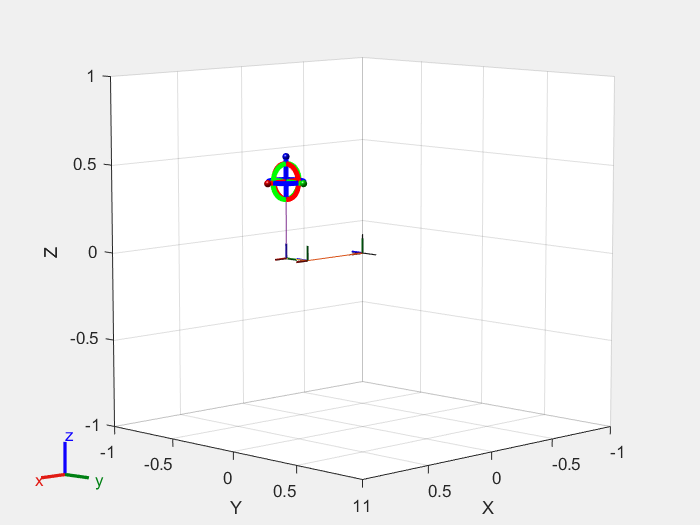

figure
intRobotPuma560 = interactiveRigidBodyTree(robotPuma560,MarkerScaleFactor=0.5); 

#### Example 3) DH convention

Now let's build a model of a robot arm that we have just solve in class. In this case we have also prismatic joints

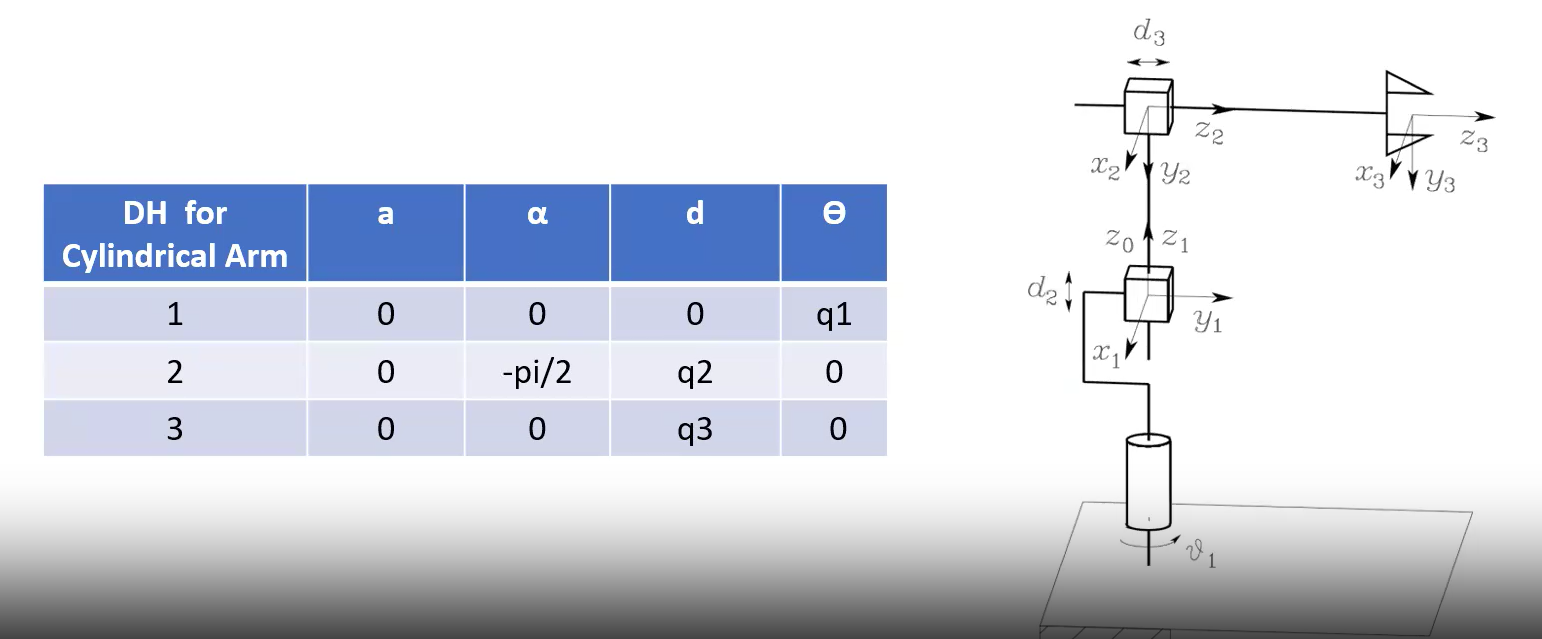

dhparams = [0 0 0 0; 0 -pi/2 0 0; 0 0 0 0];
cyl_arm = rigidBodyTree(DataFormat='row');
bodies = cell(3,1); joints = cell(3,1);
for i = 1:3
 if i == 1
 bodies{i} = rigidBody(['body' num2str(i)]);
 joints{i} = rigidBodyJoint(['jnt' num2str(i)],"revolute");
 setFixedTransform(joints{i},dhparams(i,:),"dh");
 bodies{i}.Joint = joints{i};
 else
 bodies{i} = rigidBody(['body' num2str(i)]);
 joints{i} = rigidBodyJoint(['jnt' num2str(i)],"prismatic");
 setFixedTransform(joints{i},dhparams(i,:),"dh");
 bodies{i}.Joint = joints{i};
 end
end

for i = 1:3
 if i == 1 % Add first body to base
 addBody(cyl_arm,bodies{i},"base")
 else % Add current body to previous body by name
 addBody(cyl_arm,bodies{i},bodies{i-1}.Name)
 end
end

cyl_arm.showdetails

--------------------
Robot: (3 bodies)

 Idx    Body Name   Joint Name   Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------   ----------   ----------    ----------------   ----------------
   1        body1         jnt1     revolute             base(0)   body2(2)  
   2        body2         jnt2    prismatic            body1(1)   body3(3)  
   3        body3         jnt3    prismatic            body2(2)   
--------------------


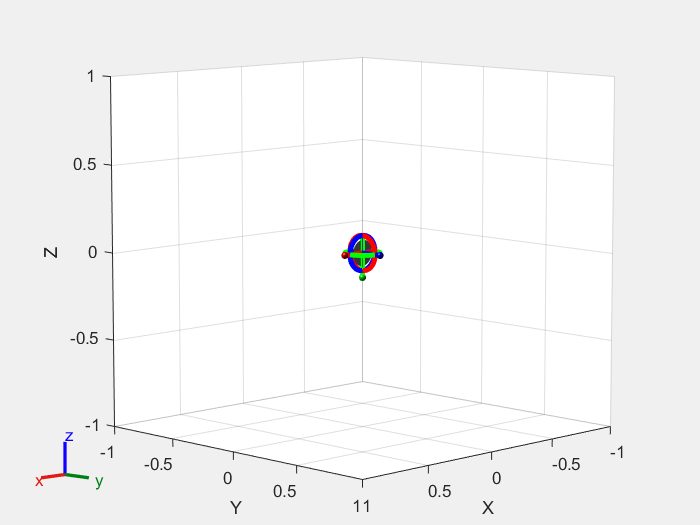

figure
int_cylarm = interactiveRigidBodyTree(cyl_arm,MarkerScaleFactor=0.5);

## Inverse Kinematic

We use IKs to compute the joint positions given the position we want to reach in the Task or Operational Space (position of the End Effector).

For **lower degree of freedom** (DOF), we can still compute the IKs **analytically** or “by hand” (also known as closed form solutions). 

For **higher DOF**, we need to trust the **numerical** computations (also known as numerical solution) 

### RVC Toolbox

#### Example 4) 2D 2-link (IK analytical solution)

We define the 2-link planar robot using the MATLAB Symbolic Toolbox

syms a1 a2 real
e2link = ETS2.Rz("q1")*ETS2.Tx(a1)*ETS2.Rz("q2")*ETS2.Tx(a2);

We compute the FK for generic q1 and q2 

syms q1 q2 real
TE = e2link.fkine([q1 q2]);

trans_v = TE(1:2,3)';

Then we define the system of equations and try to solve q1 and q2 so we can reach a desired X and Y

syms x y real
e1 = x == trans_v(1);
e2 = y == trans_v(2);

[s1,s2] = solve([e1 e2],[q1 q2])

$$s1 = \begin{array}{l} \left(\begin{array}{c} 2\,\mathrm{atan}\left(\frac{2\,a_{1}\,y-\sigma_{5}-\sigma_{4}+\sigma_{3}+\sigma_{2}+\sigma_{6}}{\sigma_{1}}\right)\\ 2\,\mathrm{atan}\left(\frac{2\,a_{1}\,y+\sigma_{5}+\sigma_{4}-\sigma_{3}-\sigma_{2}-\sigma_{6}}{\sigma_{1}}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={a_{1}}^{2}+2\,a_{1}\,x-{a_{2}}^{2}+x^{2}+y^{2}\\ \sigma_{2}=\frac{y^{2}\,\sigma_{7}}{\sigma_{8}}\\ \sigma_{3}=\frac{x^{2}\,\sigma_{7}}{\sigma_{8}}\\ \sigma_{4}=\frac{{a_{2}}^{2}\,\sigma_{7}}{\sigma_{8}}\\ \sigma_{5}=\frac{{a_{1}}^{2}\,\sigma_{7}}{\sigma_{8}}\\ \sigma_{6}=\frac{2\,a_{1}\,a_{2}\,\sigma_{7}}{\sigma_{8}}\\ \sigma_{7}=\sqrt{\sigma_{8}\,\left({a_{1}}^{2}+2\,a_{1}\,a_{2}+{a_{2}}^{2}-x^{2}-y^{2}\right)}\\ \sigma_{8}=-{a_{1}}^{2}+2\,a_{1}\,a_{2}-{a_{2}}^{2}+x^{2}+y^{2} \end{array}$$

$$s2 = \begin{array}{l} \left(\begin{array}{c} -\sigma_{1}\\ \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,\mathrm{atan}\left(\frac{\sqrt{\left(-{a_{1}}^{2}+2\,a_{1}\,a_{2}-{a_{2}}^{2}+x^{2}+y^{2}\right)\,\left({a_{1}}^{2}+2\,a_{1}\,a_{2}+{a_{2}}^{2}-x^{2}-y^{2}\right)}}{-{a_{1}}^{2}+2\,a_{1}\,a_{2}-{a_{2}}^{2}+x^{2}+y^{2}}\right) \end{array}$$

Let’s see which are the values of X and Y for q1=20 deg and q2=20 deg, so we can check our results:

xdes=eval(subs(trans_v(1),[a1 a2 q1 q2], [1 1 deg2rad(20) deg2rad(20)]))

xdes = 1.7057

ydes=eval(subs(trans_v(2),[a1 a2 q1 q2], [1 1 deg2rad(20) deg2rad(20)]))

ydes = 0.9848

And we have two set of solutions: 

sol1_q1=rad2deg(eval(subs(s1(1),[a1 a2 x y],[1 1 xdes ydes])))

sol1_q1 = 40.0000

sol1_q2=rad2deg(eval(subs(s2(1),[a1 a2 x y],[1 1 xdes ydes])))

sol1_q2 = -20.0000

sol2_q1=rad2deg(eval(subs(s1(2),[a1 a2 x y],[1 1 xdes ydes])))

sol2_q1 = 20.0000

sol2_q2=rad2deg(eval(subs(s2(2),[a1 a2 x y],[1 1 xdes ydes])))

sol2_q2 = 20.0000

It’s interesting to see that for these set of values for q1 and q2, we can obtain the same position for X and Y

printtform2d(se2(eval(subs(TE,[a1 a2 q1 q2],[1 1 deg2rad([sol1_q1 sol1_q2])]))),unit="deg")

t = (1.71, 0.985), 20 deg


printtform2d(se2(eval(subs(TE,[a1 a2 q1 q2],[1 1 deg2rad([sol2_q1 sol2_q2])]))),unit="deg")

t = (1.71, 0.985), 40 deg


#### Example 5) 2D 2-link (IK numerical solution)

Let’s see what happens with the 2-link planar robot using a numerical solution.

We want to minimize the norm of the computed position with the desired ones, so:

clear a1 a2 q1 q2
a1 = 1; a2 = 1;
e2link = ETS2.Rz("q1")*ETS2.Tx(a1)*ETS2.Rz("q2")*ETS2.Tx(a2);
pdes=[1.7057 0.9848];
q=fminsearch(@(q) norm(se2(e2link.fkine(q)).trvec-pdes),[0 0]);
rad2deg(q)

ans =    19.9952   20.0107


As we can see we have more or less 20° for each revolut joint.

#### Example 6) 3D ABB robotic arm (IK analytical solution)

Since the wrist motion cause zero translational motion, we can state that the end-effector position is a function only of the first three joints  

abb = loadrobot("abbIrb1600",DataFormat="row");
abb.showdetails

--------------------
Robot: (7 bodies)

 Idx     Body Name           Joint Name           Joint Type     Parent Name(Idx)   Children Name(s)
 ---     ---------           ----------           ----------     ----------------   ----------------
   1        link_1              joint_1             revolute         base_link(0)   link_2(2)  
   2        link_2              joint_2             revolute            link_1(1)   link_3(3)  
   3        link_3              joint_3             revolute            link_2(2)   link_4(4)  
   4        link_4              joint_4             revolute            link_3(3)   link_5(5)  
   5        link_5              joint_5             revolute            link_4(4)   link_6(6)  
   6        link_6              joint_6             revolute            link_5(5)   tool0(7)  
   7         tool0        joint_6-tool0                fixed            link_6(6)   
--------------------


To retrive the analytical IK function we can use the following command

aIK=analyticalInverseKinematics(abb);
aIK.showdetails

--------------------
Robot: (7 bodies)

Index      Base Name   EE Body Name     Type                    Actions
-----      ---------   ------------     ----                    -------
    1      base_link         link_6   RRRSSS   Use this kinematic group
    2      base_link          tool0   RRRSSS   

Note that there two groups: one considers the link6 as the end of the robot, and the other one considers a tool connected to link6. The difference is that the tool is rotated with respect to the reference frame of link6

abb.getBody("tool0").Joint.Type

ans = 'fixed'

T=abb.getBody("tool0").Joint.JointToParentTransform;
printtform(T)

t = (0, 0, 0), RPY/zyx = (0, 1.57, 0) rad


To solve the IKs,we create a handle function for that:

abbIKFcn = aIK.generateIKFunction("ikIRB1600");

We then define the desired pose we want to reach:

des_pose=trvec2tform([0.93 0 0.5])*eul2tform([0 pi/2 0]) 

des_pose =     0.0000         0    1.0000    0.9300
         0    1.0000         0         0
   -1.0000         0    0.0000    0.5000
         0         0         0    1.0000


And finally, we solve the IK problem

qsol_cs=abbIKFcn(des_pose);
q_sol1=qsol_cs(1,:);
q_sol2=qsol_cs(2,:);

Both solutions are valid, in fact, we can also check:

T1=abb.getTransform(q_sol1,"tool0"); printtform(T1)

t = (0.93, 0, 0.5), RPY/zyx = (0, 1.57, 0) rad


T2=abb.getTransform(q_sol2,"tool0"); printtform(T2)

t = (0.93, 0, 0.5), RPY/zyx = (0, 1.57, 0) rad


#### Example 6) 3D ABB robotic arm (IK numerical solution)

We use the inverseKinematics function from MATLAB

abbIK=inverseKinematics(RigidBodyTree=abb);
abbHome=abb.homeConfiguration; %row 0 vector

abbHome =      0     0     0     0     0     0


[q_sol_ns,sol_info]=abbIK("tool0",T1,ones(1,6),abbHome);

q_sol_ns =     0.0000    0.5695    0.1306   -0.0000   -0.7000   -0.0000


sol_info = struct with fields:
           Iterations: 13
    NumRandomRestarts: 0
        PoseErrorNorm: 6.7075e-09
             ExitFlag: 1
               Status: 'success'


The second term (T1) is the desired position descrived using the Homogeneous matrix form, the third term are the weights for each joint and the last one, the first guess. In this case teh first guess is its home position. We can check the results:

T3=abb.getTransform(q_sol_ns,"tool0"); printtform(T3)

t = (0.93, 1.65e-12, 0.5), RPY/zyx = (0, 1.57, -2.6e-12) rad
